# Albert Robles Center (ARC) digital model

This script is designed as a central hub for interacting with the ARC digital model. Two independent sections are present in the code:

- Tailored simulation execution that allows for an adjustment of the power and treatment system parameters by end users. 

- Structured simulation execution used for the analysis as part of the National Alliance for Water Innovation's Project 3.25.  

A list of all adjustable parameters as designed is shown below. First, the different **local grid and power billing options** are available. This specifically includes solar generation capacities, battery toggling, and billing structures.  

Then, the options surrounding **Ultrafiltration** are presented, specifically the options to enable UF shutdown (disabled by default), and to modify the backwash cycle times (currently set at 55 minutes). 

Following, **Reverse Osmosis** settings are made available. First, the fouling factor of all RO membranes are made available. By default, this is set to 0% fouling. Then, the chemical stabilization time for RO is presented. This is set to 105 minutes and represents the amount of time needed for RO chemicals to stabilize following a shutdown of ALL RO skids. During this period, RO permeate is recycled back to the headworks, similar to the UF system, while the brine from TSRO is sent off site. 

Lastly, **Brine Disposal **rates are set at $/af. The default value is the 2024 brine disposal cost. 

The below section sets the current directory to the script folder and loads underlying pump, UVAOP, and UF models. *It is highly recommended to run this when first opening this script. *

%This section initializes the current directory when run. 
% Section 1: Select month and get specific data from grip reports.
 
% this returns the full path to the current file (function or script)
fullFileName = matlab.desktop.editor.getActiveFilename;

% split off the folder
[folderPath, ~, ~] = fileparts(fullFileName);

%add complete folder & subfolders to cd
cd(folderPath)
addpath(genpath(folderPath));

%Load overarching model
simulink_model = "ARC_DTm";
open_system(simulink_model);

%Load underlying models into workspace.
% UVAOP ANNs
try
    if ~exist('net_1flow', 'var') || ~exist('net_2flow', 'var')
        load('UVAOP_ANN_Flow.mat', 'net_1flow', 'net_2flow');
        disp('UVAOP ANNs loaded')
    else
        disp('UVAOP ANNs already in workspace.')
    end
catch ME
    error('Failed to load UVAOP_ANN_Flow.mat: %s', ME.message);
end

UVAOP ANNs already in workspace.



%UF, PROS1, PROS2, and TSRO pump loads. 
try
    load("Pumps\LookupTables.mat")
    disp('Pump lookup tables loaded')
catch ME
    error('Failed to load pump lookup tables. Please see Pumps/LookupTables.mat. \n %s', ME.message)
end

Pump lookup tables loaded



%UF Fouling model
try
    LUT_load = load("gamLUT.mat");
    LUT = LUT_load.gamLUT;
    initUF;
    disp('UF Fouling model loaded.')
catch ME
    error('Failed to load UF fouling model. Please see UF/ufFoulingPred_GAM.mat. \n %s', ME.message)
end

Priming UF Model. Loading...


UF Fouling model loaded.


## Grid Conditions

The grid relevant to operations at ARC is customizable to the scenario of interest. Through NAWI 3.25, the following local grid behavior can be modigied for analysis:

**1) Solar Capacity:  **The amount of solar available to be generated on-site. ***Note: ***All expanded solar is assumed to have the same behavior as existing solar. This behavior can be modified through the *Solar Scenario Data *modifier. The list of available solar scenarios can be further expanded by using the *solarDataExtraction.mlx *function. 

maximum_solar_generation = 1300;
solarModifier = maximum_solar_generation / 300; %this is passed to the simulation

solar_generation_worksheet_options =  dir(fullfile(folderPath,"SolarSimulationData","*.xls*"));
solar_generation_worksheet_names = string({solar_generation_worksheet_options.name})';

solar_generation_worksheet = solar_generation_worksheet_names(1);

%the below block enables different sizes of solar data to be used in the
%simulation
solar_file_name = fullfile(folderPath, "SolarSimulationData", solar_generation_worksheet);
solar_data_length = length(readcell(solar_file_name));
solar_range_string = "D1:D"+solar_data_length;
%Set block in simulink to the entire range of the solar dataset. 
%This allows for spreadsheets with different ranges to be used without error. 
solar_import_block_path = 'ARC_DTm/Plant Setpoints/SolarImport';
set_param(solar_import_block_path,"FileName",solar_file_name, ...
    "Range", solar_range_string, "TreatFirstColumnAs", "Data", "OutputAfterLastPoint", "Repeating sequence", "SampleTime","1");


 

**2) Time-of-Use Variance & Demand Charges:** The time-of-use variance ($/kWh) over the course of the day based on winter rates. The static TOU holds the daily average of $0.370 per kWh consumed. Both the existing and expanded TOU rates maintain the same daily average and follow the same peaking periods: 

*11am-4pm, Super Off Peak | 4pm - 9pm, On Peak | 9pm - 11am, Off Peak.* 

These align with the demand charge periods as well. The demand charge values can be modified below as well, with default values representing the winter demand rates. This is calculated at the end of the simulation window. The on-peak window for demand charges can be adjusted using the slider below. 

Additionally, the Electricity Sale Price Modifier determines how much power can be sold for *back *to the grid should there be excess power on site or as part of a battery arbitrage approach. This is represented as a percent of the TOU rate where 100% means $/kWh sold = $/kWh purchased. 

Electricity_SalePriceModifier = 50/100; %this is passed direct to simulation

%this is used to define the control below and to point simulink towards the
%spreadsheet.
TOU_file = "_TOURates.xlsx";
TOU_sheet_names = sheetnames(TOU_file);

%TOU cases used to define the From Spreadsheet block sheet. 
TOU_case = TOU_sheet_names(1); %this is passed direct to simulation. 
TOU_block_path = "ARC_DTm/Plant Setpoints/TOURateImport";
set_param(TOU_block_path, "FileName",TOU_file,"SheetName",TOU_case, ...
    "Range", "", "TreatFirstColumnAs", "Data", "OutputAfterLastPoint", "Repeating sequence", "SampleTime","1");
 
%Demand Charges
peak_demand_charge = 3.27;
offpeak_demand_charge = 23.28;
peak_window = [16 21];
window_min = peak_window(1) / 60;
window_max = peak_window(2) / 60;


**3) Battery Scenario: **A battery is available for simulation on-site. The current implementation of the battery begins charging when solar power exceeds local process load demand. If the battery is disabled here, excess power is automatically sold back to the grid. 

batteryScenario = 2;

## Ultrafiltration 

#### Shutdown and maintenance

By default, the UF system goes into circulation during a system shutdown, resulting in a continuous flow into the UF system through the plant feed pumps at a rate of 50% of plant capacity (5833 gpm). In this scenario, flow from the UF is recycled back to the headworks. 

By checking the box below, the shutdown can be enabled to allow for a complete stoppage of flow into the UF system when the plant productions setpoint drops to zero. 

Additionally, the backwash cycle time (i.e. time in operations between backwash cycles) can be defined. The default is 55 minutes. A higher cycle time leads to less frequent maintenance.

Lastly, the static UF recovery rate can be adjusted. The minimum membrane recovery is 96% in design documentation with a maximum of 100%. 

UF_ShutdownEnabled = true;
if ~UF_ShutdownEnabled
    minimum_UF_system_flow = 5833; %gpm
else 
    minimum_UF_system_flow = 0; %gpm
end

UF_BWCycleTime = 55;
UF_RecoveryRate=96;

## Reverse Osmosis

This section allows for adjustments to the RO system by changing the chemical stabilization time and the recovery rate for each stage. The chemical stabilization time activates when the flow to the RO system ramps up after being set at 0 gpm. This stabilization time is deterministic and routes all permeate back to the EQ basin. During this period, the system sets the RO system at a 1x1 configuration to limit permeate generation losses. 

The recovery rate setpoint determines the recovery rate by stage. The standards are set as the median recovery rate during 2021. 

To change membrane characteristics, please edit the *Initialize_ReverseOsmosis.m* file. 

ROstabilization_time = 105;
PROS1_recoveryrate = 61;
PROS2_recoveryrate = 62;
TSRO_recoveryrate = 51;
Initialize_ReverseOsmosis;

Initializing RO Membrane Values.


## Brine Disposal

This changes the $/acre-foot brine disposal cost, calculated at the end of the simulation period. Currently, this is only calculated based on brine volume, not water quality. 

brine_disposal_rate_dolaf = 517.96;
brine_disposal_rate_dolMG = brine_disposal_rate_dolaf / .3259;

## Controls Strategy

The controls strategy (plant flow setpoints) should be defined in an Excel spreadsheet prior to running this simulation. This spreadsheet should contain the Feed flow rate setpoint. 

%Give users the ability to select the spreadsheet
%allow the selection of the case
operations_setpoints_spreadsheet = "OperationalScenarios.xlsx";
operations_setpoints_sheet_names = sheetnames(operations_setpoints_spreadsheet);
operations_case = operations_setpoints_sheet_names(4);
operations_import_block_path = "ARC_DTm/Plant Setpoints/Controls";
set_param(operations_import_block_path,"FileName",operations_setpoints_spreadsheet, ...
    "Range", "", "SheetName",operations_case,"TreatFirstColumnAs", "Time", "SampleTime","1");

 

# `Run Simulation`

Once the simulation setting are ready, press the below button to run the simulation. This will run the above sections before executing the simulation.  

%Activate the entire script before running function. 
%This button lets users activate all cells
disp("Running simulation.")

Running simulation.


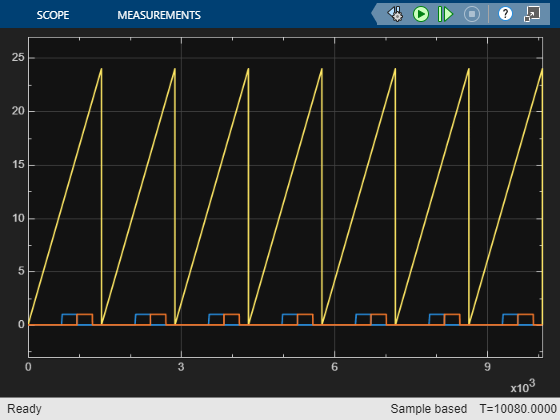

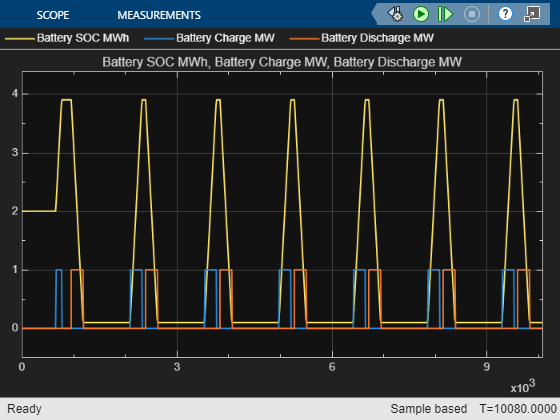

Sim Time: 6.68 min

 
%this is used to supress algebraic loop messages from EPRI controls 
set_param(simulink_model, "AlgebraicLoopMsg", "none");
set_param(simulink_model, "IntegerOverflowMsg", "none");

% Open the Simulink model for simulation
%open_system(simulink_model);

% Run the simulation
simOut = sim(simulink_model);

disp('Simulation completed successfully.');

Simulation completed successfully.


#### Saving and Plotting

By default, the code saves summary results to an overarching table across runs and saves figures presenting key timeseries plots to a folder specific to this run in the *Results* folder. The standard folder naming convention is:

Results/Visualizations*/operationscase_maximumsolargeneration_TOUCase*

where the operations case, solar generation, and TOU case are pulled from the entries in this script. This can be changed using the provided box, if desired. For a complete list of parameters and plots, please see *postSimAnalysis.m.*

results_save = true;
plot_save = true;

results_folder = fullfile(folderPath,"Results");
run_folder_suggested = fullfile(results_folder, "Visualizations",operations_case + "_"+num2str(maximum_solar_generation) + "kWSolar_"+TOU_case);
run_folder = "C:\Users\joshl\Desktop\ARC_Complete\Results\Visualizations\SteadyState_1300kWSolar_ExistingTOU";

if ~exist(run_folder, 'dir')
    mkdir(run_folder)
end

disp('Generating figures and saving run results.')

Generating figures and saving run results.


 
postSimAnalysis;

Unrecognized function or variable 'Battery_Scenario'.

Error in postSimAnalysis (line 77)
    Battery_Scenario, ...
    ^^^^^^^^^^^^^^^^^^^^^